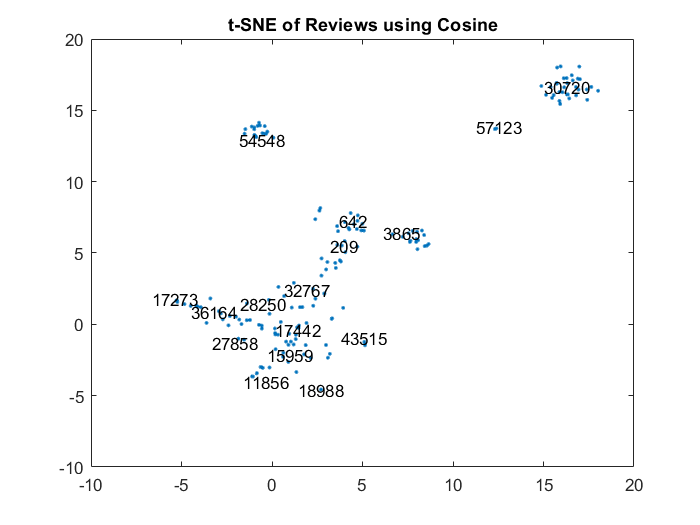

% This is for Task 7

% This accesses the data matrix which contains all information
% Associated with the reviews. 
reviewsIDs = data.ID;
% This converts the reviews IDs to strings so they can be used in
% The textscatter plot
reviewIDs_string =  string(reviewsIDs);

% This computes the t-sne reduction of the reviews using the best model
% with a cosine distance metric
% The best model contains the DocumentScores which are the vectorized
% version of the reviews used to create the LSA model
t_cosine = tsne(bestModel.DocumentScores,"distance",'cosine');

% Creating a figure to plot
figure
textscatter(t_cosine(:,1),t_cosine(:,2),reviewIDs_string)
title("t-SNE of Reviews using Cosine");

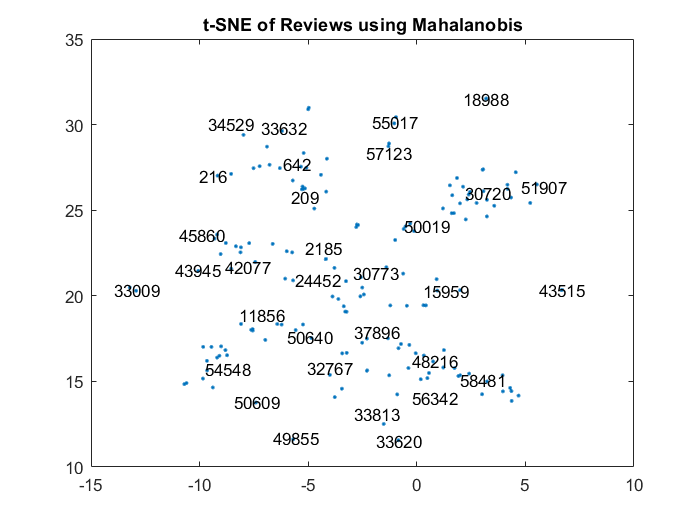


% This computes the t-sne reduction of the reviews using the best model
% with a mahalanobis distance metric
% The best model contains the DocumentScores which are the vectorized
% version of the reviews used to create the LSA model
t_mahalanobis = tsne(bestModel.DocumentScores,'Distance','mahalanobis');

% Creating a figure to plot
figure
textscatter(t_mahalanobis(:,1),t_mahalanobis(:,2),reviewIDs_string)
title("t-SNE of Reviews using Mahalanobis");

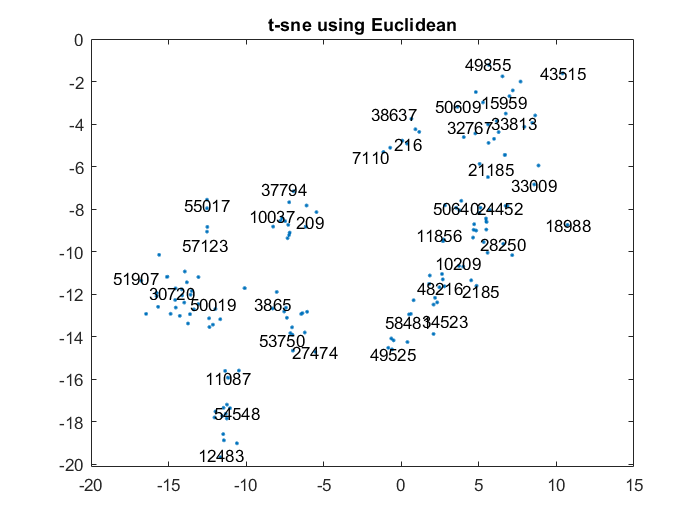


% Creating a t-sne using euclidean distances
t_euclidean = tsne(bestModel.DocumentScores,"distance","euclidean");
% Plotting the euclidean things
figure
textscatter(t_euclidean(:,1),t_euclidean(:,2),reviewIDs_string)
title("t-sne using Euclidean")

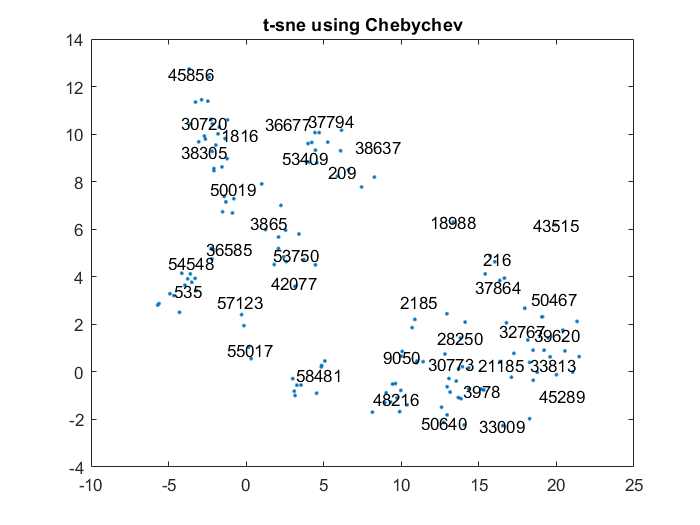


% Computing a tsne reduciotn using chebychev distances
t_chebychev = tsne(bestModel.DocumentScores,"distance","chebychev");
% Plotting the results from chebycheb
figure
textscatter(t_chebychev(:,1),t_chebychev(:,2),reviewIDs_string)
title("t-sne using Chebychev")